clear all
close all
clc

**6. Filtros de Bloom**

Crie um conjunto de funcoes Matlab que implementem as funcionalidades de um Bloom Filter basico. As funcoes devem ter os parametros necessarios para que seja possivel criar Bloom Filters de diferentes tamanhos (n) e a utilizacao de diferentes numeros de funcoes de dispersao (k). Na criacao das diferentes funcoes de dispersao, adote o terceiro metodo descrito no slide “Como ter n funcoes de dispersao ?” da apresentacao TP sobre funcoes de dispersao com a funcao que considera ter tido o melhor desempenho na experiencias que efetuou na seccao 6.2. Sugestao: Criar pelo menos 3 funcoes: uma para inicializar a estrutura de dados; outra para inserir um elemento (ou elementos) no filtro; uma terceira para verificar se um elemento pertence ao conjunto. 

1. Com as funcoes que desenvolveu, crie um Bloom Filter para guardar um conjunto, U1, de 1000 palavras diferentes. Use um Bloom Filter de tamanho n = 8000 e k = 3 funcoes de dispersao. 

char_set = ['a':'z' 'A':'Z' '0':'9'];  
imin = 5; 
imax = 10; 
N = 1000; 

U1 = gerador_chaves(N, imin, imax, char_set, ones(1, length(char_set)));

n = 8000; 
k = 3;     

BF = InitializerBF(n);

for i = 1:length(U1)
    BF = AddBF(BF, U1{i}, k);  
end

check1 = CheckBF(BF, 'exemplo', k)  % Verificar palavra 'exemplo'

check1 = logical
   0


check2 = CheckBF(BF, 'teste', k)    % Verificar palavra 'teste'

check2 = logical
   0


2. Teste o Bloom Filter criado anteriormente, verificando a pertenca de todas as palavras do conjunto U1. Obteve algum falso negativo? 

falsos_negativos = 0; 

for i = 1:length(U1)
    if ~CheckBF(BF, U1{i}, k)  
        falsos_negativos = falsos_negativos + 1;
    end
end

if falsos_negativos == 0
    fprintf('Nenhum falso negativo encontrado. O Bloom Filter está a funcionar corretamente!\n');
else
    fprintf('Falsos negativos encontrados: %d\n', falsos_negativos);
end

Nenhum falso negativo encontrado. O Bloom Filter está a funcionar corretamente!


3. Teste o Bloom Filter criado anteriormente, verificando a pertenca de um novo conjunto, U2, com 100000 palavras todas diferentes das de U1. Indique a percentagem de falsos positivos obtidos. 

N2 = 100000;  
U2 = gerador_chaves(N2, imin, imax, char_set, ones(1, length(char_set)));

falsos_positivos = 0; 

for i = 1:length(U2)
    if CheckBF(BF, U2{i}, k) 
        falsos_positivos = falsos_positivos + 1;
    end
end

percentual_fp = (falsos_positivos / N2) * 100;

fprintf('Número de falsos positivos: %d\n', falsos_positivos);

Número de falsos positivos: 3242


fprintf('Percentagem de falsos positivos: %.2f%%\n', percentual_fp);

Percentagem de falsos positivos: 3.24%


4. Compare a percentagem de falsos positivos obtida anteriormente com a estimativa que aprendeu nas TPs. 

m = 1000; 
n = 8000;
k = 3;     

% Cálculo teórico da taxa de falsos positivos
FP_teorico = (1 - exp(-k * m / n))^k;

fprintf('Estimativa teórica de falsos positivos: %.2f%%\n', FP_teorico * 100);

Estimativa teórica de falsos positivos: 3.06%


fprintf('Percentagem de falsos positivos (prático): %.2f%%\n', percentual_fp);

Percentagem de falsos positivos (prático): 3.24%


fprintf('Diferença entre teórico e prático: %.2f%%\n', abs(FP_teorico * 100 - percentual_fp));

Diferença entre teórico e prático: 0.18%


5. Repita os exercicios 1 e 3 para um numero de funcoes de dispersao k de 4 ate 10. Faca um grafico com a percentagem de falsos positivos em funcao de k. Analisando os resultados, qual o valor otimo k? Compare este valor com o valor teorico que aprendeu nas TPs.

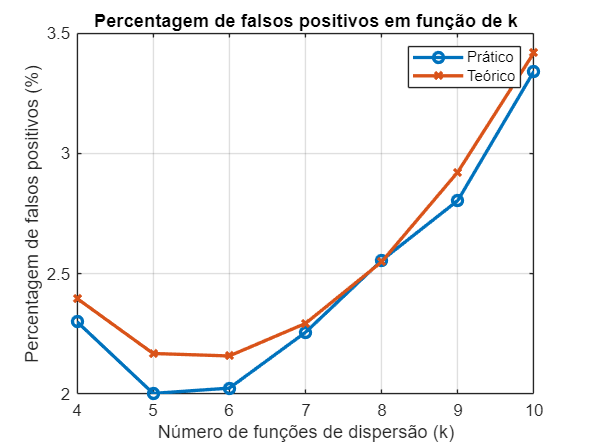

m = 1000;   
n = 8000;   
k_values = 4:10; 
N2 = 100000; 

% Gerar o conjunto U1 e U2
char_set = ['a':'z' 'A':'Z' '0':'9']; 
imin = 5;  
imax = 10; 
U1 = gerador_chaves(m, imin, imax, char_set, ones(1, length(char_set)));
U2 = gerador_chaves(N2, imin, imax, char_set, ones(1, length(char_set)));

falsos_positivos_percentual = zeros(1, length(k_values));
falsos_positivos_teorico = zeros(1, length(k_values));

for idx = 1:length(k_values)
    k = k_values(idx);
    
    BF = InitializerBF(n);
    
    for i = 1:length(U1)
        BF = AddBF(BF, U1{i}, k);
    end
    
    falsos_positivos = 0;
    for i = 1:length(U2)
        if CheckBF(BF, U2{i}, k)
            falsos_positivos = falsos_positivos + 1;
        end
    end
    
    % Calcular percentagem de falsos positivos
    falsos_positivos_percentual(idx) = (falsos_positivos / N2) * 100;
    
    % Calcular o valor teórico para k
    falsos_positivos_teorico(idx) = (1 - exp(-k * m / n))^k * 100;
end


figure;
plot(k_values, falsos_positivos_percentual, 'o-', 'LineWidth', 2, 'DisplayName', 'Prático');
hold on;
plot(k_values, falsos_positivos_teorico, 'x-', 'LineWidth', 2, 'DisplayName', 'Teórico');
xlabel('Número de funções de dispersão (k)');
ylabel('Percentagem de falsos positivos (%)');
title('Percentagem de falsos positivos em função de k');
legend('show');
grid on;


% Determinar o valor ótimo de k
[~, idx_otimo] = min(falsos_positivos_percentual);
k_otimo = k_values(idx_otimo);
fprintf('Valor ótimo de k (prático): %d\n', k_otimo);

Valor ótimo de k (prático): 5



% Comparar com o valor ótimo teórico
k_teorico = round((n / m) * log(2));  % Fórmula teórica do valor ótimo de k
fprintf('Valor ótimo de k (teórico): %d\n', k_teorico);

Valor ótimo de k (teórico): 6
